This script is for analysis on the dateset that was used trying to understand the changes of the histogram peak channels. The dateset could be found at z:yaochen/Active/Pingchuan/2022SPR/20220125_PeakTest_AchSensor_001.

The acqns 10-13 are all 10-min recordings at different laser power to get different photon counts.

The acqns 14-16 are 10-min recordings that were done with repeatedly taking off and putting back of the patch cord close to the PMT site.

The first two sessions of the analysis is to FLP analysis of acqns 10-16.

ExperimentName='20220125_PeakTest_AchSensor_001'; 
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 7; % How many chunks of recordings are there?

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 


Before running this session, load the FLIM files in spc_main and doing the fitting and fixation of the paramteres.

for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'h.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end


This session is to export the information of the peak channels of the acqns.

max_points_all=[];
photoncount_all=[];
histograms_40=[];
histograms_41=[];
histograms_42=[];
histograms_43=[];


for i=1:number_of_acq
    filename=[analysis_name,num2str(i),'h.mat'];
    load(filename)
    eval(['max_points_',num2str(i),'=zeros(1, size(lifetime_histograms, 2));'])
    for j=1:size(lifetime_histograms, 2)
        single_histogram=lifetime_histograms(:,j);
        eval(['max_points_',num2str(i),'(',num2str(j),')=mean(find(single_histogram==max(single_histogram)));'])
        
        if find(single_histogram==max(single_histogram))==39
            histograms_39=[histograms_39 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==40
            histograms_40=[histograms_40 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==41
            histograms_41=[histograms_41 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==42
            histograms_42=[histograms_42 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==43
            histograms_43=[histograms_43 single_histogram/max(single_histogram)];
        end
    end
    eval(['max_points_all=[max_points_all max_points_',num2str(i),'];'])
    photoncount_all=[photoncount_all photoncount'];
%     figure
%     eval(['histogram(max_points_',num2str(i),')'])
    
end

save([ExperimentName,'_peaks.mat'])

Saving wave object  ...
Saving wave object  ...
Saving wave object  ...


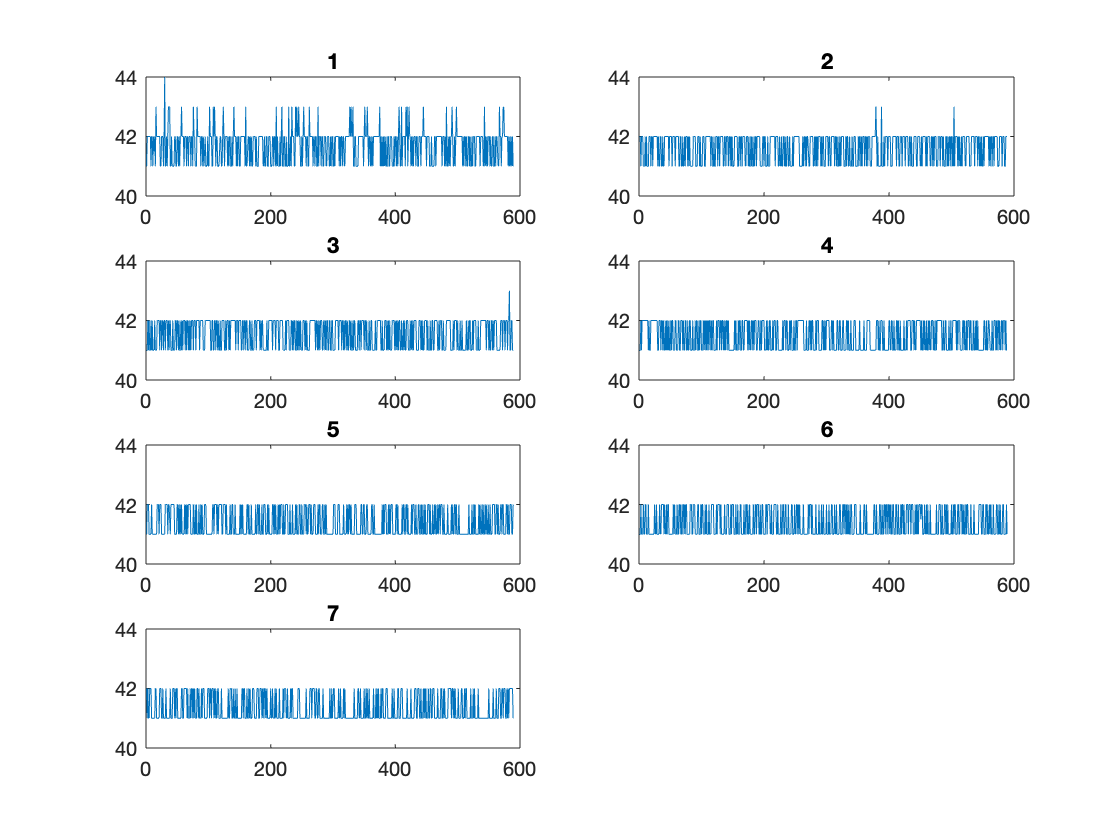

for i=1:number_of_acq
    subplot(ceil(number_of_acq/2),2,i)
    eval(['plot(max_points_',num2str(i),')'])
    ylim([40 44])
    title(num2str(i))
end

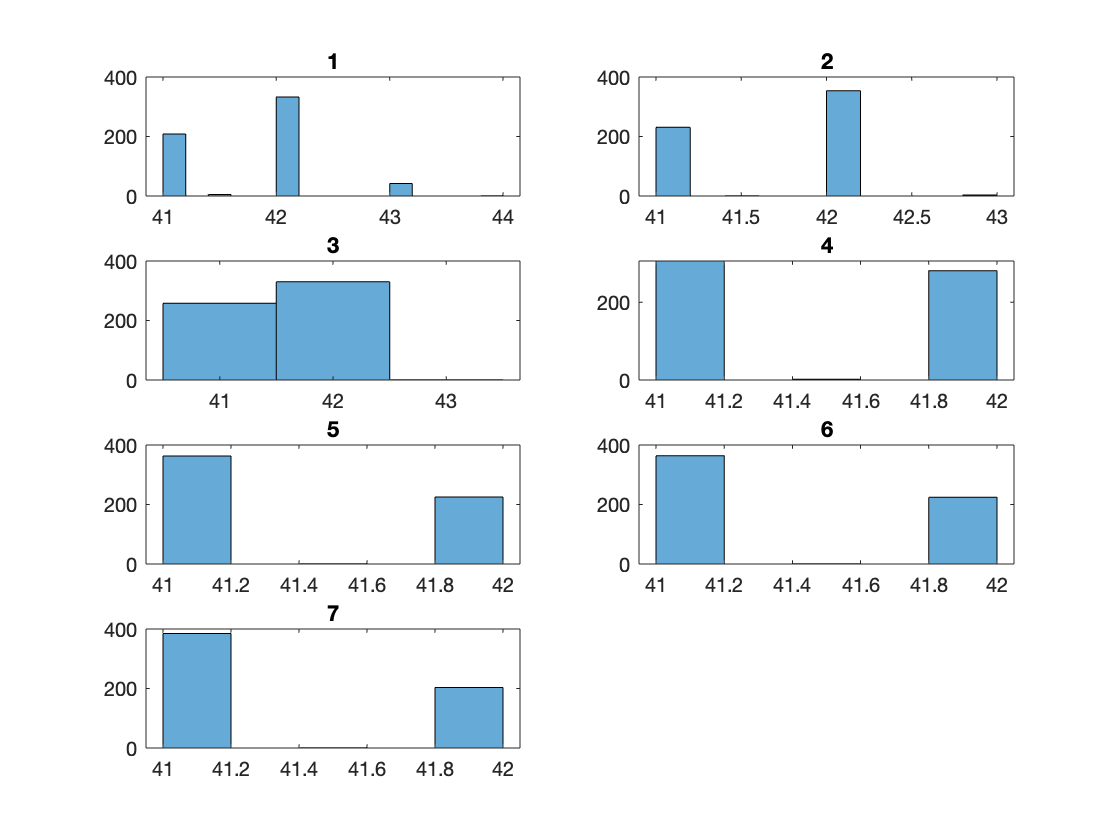

for i=1:number_of_acq
    subplot(ceil(number_of_acq/2),2,i)
    eval(['histogram(max_points_',num2str(i),')'])
    title(num2str(i))
end